% =================================================================
% PHANTOM X PINCHER - AUTOMATED KINEMATIC CALIBRATION SUITE
% =================================================================
clear; clc;

% 1. DEFINE TEST CONFIGURATIONS (Units: Radians)
% Each row is a test case: [theta1, theta2, theta3, theta4]
% Ensure these poses are physically safe and won't hit the table!
% 1. DEFINE TEST CONFIGURATIONS (Units: Radians)
% Each row is a test case: [Base, Shoulder, Elbow, Wrist]
% Using deg2rad() to make the physical poses easy to visualize.

test_cases = [
    % --- CATEGORY 1: Baselines & Panning (Testing Joint 1 Backlash) ---
    0,            0,           0,           0;             % 1: Home (Straight up)
    deg2rad(45),  0,           0,           0;             % 2: Pan Left 45°
    deg2rad(-45), 0,           0,           0;             % 3: Pan Right 45°
    deg2rad(90),  0,           0,           0;             % 4: Pan Left 90°
    deg2rad(-90), 0,           0,           0;             % 5: Pan Right 90°

    % --- CATEGORY 2: Pure Forward Reaches (Testing Gravity Sag on J2 & J3) ---
    0,            deg2rad(30), deg2rad(0),  deg2rad(0);    % 6: Shallow reach
    0,            deg2rad(45), deg2rad(45), deg2rad(0);    % 7: Mid reach (Standard pick distance)
    0,            deg2rad(60), deg2rad(30), deg2rad(-30);  % 8: Far reach (Wrist curled up to avoid table)
    0,            deg2rad(20), deg2rad(70), deg2rad(0);    % 9: Heavy elbow bend

    % --- CATEGORY 3: Asymmetrical Compound Poses (Testing diagonal stress) ---
    deg2rad(30),  deg2rad(45), deg2rad(45), deg2rad(0);    % 10: Pan Left + Mid reach
    deg2rad(-30), deg2rad(45), deg2rad(45), deg2rad(0);    % 11: Pan Right + Mid reach
    deg2rad(60),  deg2rad(30), deg2rad(60), deg2rad(-15);  % 12: Pan Far Left + Complex bend
    deg2rad(-60), deg2rad(60), deg2rad(15), deg2rad(-45);  % 13: Pan Far Right + Low reach

    % --- CATEGORY 4: Wrist Extremes (Testing the lightest joint) ---
    0,            deg2rad(45), deg2rad(45), deg2rad(90);   % 14: Mid reach, Wrist pointing straight DOWN
    0,            deg2rad(45), deg2rad(45), deg2rad(-90);  % 15: Mid reach, Wrist pointing straight UP
    deg2rad(45),  deg2rad(30), deg2rad(30), deg2rad(60);   % 16: Pan + Reach + Wrist Down
    deg2rad(-45), deg2rad(30), deg2rad(30), deg2rad(-60);  % 17: Pan + Reach + Wrist Up

    % --- CATEGORY 5: "Snake" / Edge Cases (Testing complex inverse loading) ---
    deg2rad(15),  deg2rad(45), deg2rad(-45), deg2rad(45);  % 18: Shoulder forward, Elbow back, Wrist forward
    deg2rad(-15), deg2rad(-15),deg2rad(45),  deg2rad(-30); % 19: Leaning backward slightly, reaching forward
    0,            deg2rad(20), deg2rad(20),  deg2rad(20);  % 20: Gentle resting curve
];
num_tests = size(test_cases, 1);
error_history_deg = zeros(num_tests, 4); % Matrix to store errors for final average

% 2. INITIALIZE ROBOT CONNECTION
port = 'COM5'; 
numServos = 5; 

try
    arb = Arbotix('port', port, 'nservos', numServos);
    fprintf('Successfully connected to Pincher on %s\n\n', port);
catch
    error('Could not connect. Ensure %s is free and the robot is powered on.', port);
end

serPort COM5is in use.   Closing it.


i = 4

Successfully connected to Pincher on COM5




fprintf('Starting Automated Kinematics Test Suite (%d Poses)...\n', num_tests);

Starting Automated Kinematics Test Suite (20 Poses)...


pause(2);

% =================================================================
% 3. EXECUTE TEST LOOP
% =================================================================
for t = 1:num_tests
    fprintf('\n============================================================\n');
    fprintf('RUNNING TEST CASE %d / %d\n', t, num_tests);
    
    % A. Get the joint angles for this specific test
    q_test = test_cases(t, :);
    
    % B. Calculate Forward Kinematics to generate the target coordinate
    % Assumes pincherFK returns [X, Y, Z, R, Theta, Phi]
    [X, Y, Z, R, Theta, Phi] = pincherFK(q_test);
    fprintf('FK Target Generated: X=%.2f, Y=%.2f, Z=%.2f, Phi=%.2f°\n', X, Y, Z, rad2deg(Phi));
    
    % C. Calculate Inverse Kinematics for that target
    currentConfig = arb.getpos();
    commanded_angles = findSolution(X, Y, Z, Phi, currentConfig);
    
    if isempty(commanded_angles)
        fprintf('WARNING: Target is mathematically out of reach! Skipping...\n');
        continue; % Skip to the next test case
    end
    
    % D. Command the physical robot
    fprintf('Moving robot to calculated IK pose...\n');
    for i = 1:4
        arb.setpos(i, commanded_angles(i), 100);
    end
    
    % Wait for arm to move and settle under gravity
    pause(10); 
    
    % E. Measure actual physical angles
    actual_angles_full = arb.getpos();
    actual_angles = actual_angles_full(1:4); % Only grab the 4 arm joints
    
    % F. Calculate and store error (Commanded - Actual)
    error_rad = commanded_angles - actual_angles;
    error_history_deg(t, :) = rad2deg(error_rad);
    
    % Display iteration results
    joint_names = {'J1 (Base)', 'J2 (Shld)', 'J3 (Elbw)', 'J4 (Wrst)'};
    for j = 1:4
        fprintf('%s | Cmd: %7.2f° | Act: %7.2f° | Err: %6.2f°\n', ...
            joint_names{j}, rad2deg(commanded_angles(j)), rad2deg(actual_angles(j)), error_history_deg(t, j));
    end
end

RUNNING TEST CASE 1 / 20


FK Target Generated: X=0.00, Y=0.00, Z=403.47, Phi=0.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J2 (Shld) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J3 (Elbw) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J4 (Wrst) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°


RUNNING TEST CASE 2 / 20


FK Target Generated: X=0.00, Y=0.00, Z=403.47, Phi=0.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J2 (Shld) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J3 (Elbw) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J4 (Wrst) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°


RUNNING TEST CASE 3 / 20


FK Target Generated: X=0.00, Y=0.00, Z=403.47, Phi=0.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J2 (Shld) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J3 (Elbw) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J4 (Wrst) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°


RUNNING TEST CASE 4 / 20


FK Target Generated: X=0.00, Y=0.00, Z=403.47, Phi=0.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J2 (Shld) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J3 (Elbw) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J4 (Wrst) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°


RUNNING TEST CASE 5 / 20


FK Target Generated: X=0.00, Y=0.00, Z=403.47, Phi=0.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J2 (Shld) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J3 (Elbw) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J4 (Wrst) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°


RUNNING TEST CASE 6 / 20


FK Target Generated: X=140.84, Y=0.00, Z=365.73, Phi=30.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J2 (Shld) | Cmd:   30.00° | Act:   31.35° | Err:  -1.35°
J3 (Elbw) | Cmd:    0.00° | Act:    0.29° | Err:  -0.29°
J4 (Wrst) | Cmd:   -0.00° | Act:    0.00° | Err:  -0.00°


RUNNING TEST CASE 7 / 20


FK Target Generated: X=251.68, Y=0.00, Z=194.19, Phi=90.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J2 (Shld) | Cmd:   45.00° | Act:   47.17° | Err:  -2.17°
J3 (Elbw) | Cmd:   45.00° | Act:   46.00° | Err:  -1.00°
J4 (Wrst) | Cmd:   -0.00° | Act:    0.00° | Err:  -0.00°


RUNNING TEST CASE 8 / 20


FK Target Generated: X=257.65, Y=0.00, Z=211.45, Phi=60.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J2 (Shld) | Cmd:   60.00° | Act:   61.82° | Err:  -1.82°
J3 (Elbw) | Cmd:   30.00° | Act:   30.76° | Err:  -0.76°
J4 (Wrst) | Cmd:  -30.00° | Act:  -30.18° | Err:   0.18°


RUNNING TEST CASE 9 / 20


FK Target Generated: X=214.31, Y=0.00, Z=218.01, Phi=90.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:    0.00° | Act:   -0.59° | Err:   0.59°
J2 (Shld) | Cmd:   20.00° | Act:   20.80° | Err:  -0.80°
J3 (Elbw) | Cmd:   70.00° | Act:   70.90° | Err:  -0.90°
J4 (Wrst) | Cmd:    0.00° | Act:    0.00° | Err:   0.00°


RUNNING TEST CASE 10 / 20


FK Target Generated: X=217.96, Y=125.84, Z=194.19, Phi=90.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:   30.00° | Act:   29.30° | Err:   0.70°
J2 (Shld) | Cmd:   45.00° | Act:   47.17° | Err:  -2.17°
J3 (Elbw) | Cmd:   45.00° | Act:   45.70° | Err:  -0.70°
J4 (Wrst) | Cmd:   -0.00° | Act:    0.29° | Err:  -0.29°


RUNNING TEST CASE 11 / 20


FK Target Generated: X=217.96, Y=-125.84, Z=194.19, Phi=90.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:  -30.00° | Act:  -29.88° | Err:  -0.12°
J2 (Shld) | Cmd:   45.00° | Act:   47.17° | Err:  -2.17°
J3 (Elbw) | Cmd:   45.00° | Act:   46.00° | Err:  -1.00°
J4 (Wrst) | Cmd:   -0.00° | Act:    0.00° | Err:  -0.00°


RUNNING TEST CASE 12 / 20


FK Target Generated: X=113.93, Y=197.33, Z=230.37, Phi=75.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:   60.00° | Act:   59.77° | Err:   0.23°
J2 (Shld) | Cmd:   30.00° | Act:   31.64° | Err:  -1.64°
J3 (Elbw) | Cmd:   60.00° | Act:   60.94° | Err:  -0.94°
J4 (Wrst) | Cmd:  -15.00° | Act:  -15.23° | Err:   0.23°


RUNNING TEST CASE 13 / 20


FK Target Generated: X=113.01, Y=-195.73, Z=266.09, Phi=30.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:  -60.00° | Act:  -59.77° | Err:  -0.23°
J2 (Shld) | Cmd:   60.00° | Act:   61.82° | Err:  -1.82°
J3 (Elbw) | Cmd:   15.00° | Act:   15.53° | Err:  -0.53°
J4 (Wrst) | Cmd:  -45.00° | Act:  -45.70° | Err:   0.70°


RUNNING TEST CASE 14 / 20


FK Target Generated: X=174.77, Y=0.00, Z=117.28, Phi=180.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:    0.00° | Act:    0.00° | Err:   0.00°
J2 (Shld) | Cmd:   45.00° | Act:   47.17° | Err:  -2.17°
J3 (Elbw) | Cmd:   45.00° | Act:   46.00° | Err:  -1.00°
J4 (Wrst) | Cmd:   90.00° | Act:   90.23° | Err:  -0.23°


RUNNING TEST CASE 15 / 20


FK Target Generated: X=174.77, Y=0.00, Z=271.10, Phi=0.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:    0.00° | Act:    0.00° | Err:   0.00°
J2 (Shld) | Cmd:   45.00° | Act:   47.17° | Err:  -2.17°
J3 (Elbw) | Cmd:   45.00° | Act:   46.00° | Err:  -1.00°
J4 (Wrst) | Cmd:  -90.00° | Act:  -90.53° | Err:   0.53°


RUNNING TEST CASE 16 / 20


FK Target Generated: X=145.99, Y=145.99, Z=223.20, Phi=120.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:   45.00° | Act:   44.53° | Err:   0.47°
J2 (Shld) | Cmd:   30.00° | Act:   31.93° | Err:  -1.93°
J3 (Elbw) | Cmd:   30.00° | Act:   30.76° | Err:  -0.76°
J4 (Wrst) | Cmd:   60.00° | Act:   60.35° | Err:  -0.35°


RUNNING TEST CASE 17 / 20


FK Target Generated: X=98.89, Y=-98.89, Z=338.56, Phi=0.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:  -45.00° | Act:  -46.00° | Err:   1.00°
J2 (Shld) | Cmd:   30.00° | Act:   31.64° | Err:  -1.64°
J3 (Elbw) | Cmd:   30.00° | Act:   31.05° | Err:  -1.05°
J4 (Wrst) | Cmd:  -60.00° | Act:  -60.64° | Err:   0.64°


RUNNING TEST CASE 18 / 20


FK Target Generated: X=122.46, Y=32.81, Z=350.96, Phi=45.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:   15.00° | Act:   14.65° | Err:   0.35°
J2 (Shld) | Cmd:    0.00° | Act:    0.88° | Err:  -0.88°
J3 (Elbw) | Cmd:   45.00° | Act:   46.00° | Err:  -1.00°
J4 (Wrst) | Cmd:   -0.00° | Act:    0.00° | Err:  -0.00°


RUNNING TEST CASE 19 / 20


FK Target Generated: X=23.85, Y=-6.39, Z=386.27, Phi=0.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:  -15.00° | Act:  -15.53° | Err:   0.53°
J2 (Shld) | Cmd:  -15.00° | Act:  -15.23° | Err:   0.23°
J3 (Elbw) | Cmd:   45.00° | Act:   45.12° | Err:  -0.12°
J4 (Wrst) | Cmd:  -30.00° | Act:  -30.47° | Err:   0.47°


RUNNING TEST CASE 20 / 20


FK Target Generated: X=167.43, Y=0.00, Z=334.89, Phi=60.00°


Moving robot to calculated IK pose...


J1 (Base) | Cmd:    0.00° | Act:   -0.29° | Err:   0.29°
J2 (Shld) | Cmd:   20.00° | Act:   20.80° | Err:  -0.80°
J3 (Elbw) | Cmd:   20.00° | Act:   20.51° | Err:  -0.51°
J4 (Wrst) | Cmd:   20.00° | Act:   19.92° | Err:   0.08°



% =================================================================
% 4. RETURN HOME
% =================================================================
fprintf('\nTests Complete. Returning to Home...\n');


Tests Complete. Returning to Home...


for i = 1:4
    arb.setpos(i, 0, 100);
end
pause(3);

% =================================================================
% 5. CALCULATE AND DISPLAY FINAL STATISTICS
% =================================================================
% Mean Signed Error: Shows directional bias (e.g., if J2 ALWAYS sags down)
mean_signed_error = mean(error_history_deg, 1);

% Mean Absolute Error: Shows total average magnitude of inaccuracy 
mean_absolute_error = mean(abs(error_history_deg), 1);

fprintf('\n\n================== FINAL DIAGNOSTIC REPORT ==================\n');



================== FINAL DIAGNOSTIC REPORT ==================


fprintf('Analysis of %d test cases across the physical workspace.\n\n', num_tests);

Analysis of 20 test cases across the physical workspace.




fprintf('                 | MEAN SIGNED ERROR | MEAN ABSOLUTE ERROR\n');

                 | MEAN SIGNED ERROR | MEAN ABSOLUTE ERROR


fprintf('-------------------------------------------------------------\n');

-------------------------------------------------------------


for j = 1:4
    fprintf('%s       |     %7.3f°     |      %7.3f°\n', ...
        joint_names{j}, mean_signed_error(j), mean_absolute_error(j));
end

J1 (Base)       |       0.425°     |        0.460°
J2 (Shld)       |      -1.018°     |        1.334°
J3 (Elbw)       |      -0.431°     |        0.724°
J4 (Wrst)       |       0.244°     |        0.332°


fprintf('=============================================================\n');


% Provide actionable advice based on the data
fprintf('\n--- HOW TO USE THIS DATA ---\n');


--- HOW TO USE THIS DATA ---


fprintf('1. If "Mean Signed Error" is consistently high (positive or negative),\n');

1. If "Mean Signed Error" is consistently high (positive or negative),


fprintf('   add that exact value as a permanent offset in your moveRobotToTarget script.\n');

   add that exact value as a permanent offset in your moveRobotToTarget script.


fprintf('2. If "Mean Absolute Error" is high but "Signed Error" is near zero,\n');

2. If "Mean Absolute Error" is high but "Signed Error" is near zero,


fprintf('   the joint has severe gear backlash (wiggle) that changes based on arm posture.\n');

   the joint has severe gear backlash (wiggle) that changes based on arm posture.


% =========================================================================
% REALSENSE HARDWARE CALIBRATION SCRIPT (Intrinsics + Extrinsics)
% =========================================================================

% --- 1. CONFIGURATION ---
% EXACT measured size of one checkerboard square in meters
squareSize = 0.025; 

% --- 2. INITIALIZE REALSENSE PIPELINE ---
pipe = realsense.pipeline();
cfg = realsense.config();

% Enable Color Stream (Depth is not strictly needed for the checkerboard math, 
% but we keep it aligned as per your setup)
cfg.enable_stream(realsense.stream.depth, 640, 480, realsense.format.z16, 30);
cfg.enable_stream(realsense.stream.color, 640, 480, realsense.format.rgb8, 30);

align_to_color = realsense.align(realsense.stream.color);

disp('Starting pipeline and warming up camera...');

Starting pipeline and warming up camera...


profile = pipe.start(cfg);

% --- 3. EXTRACT HARDWARE INTRINSICS DIRECTLY FROM CAMERA ---
% Get the color stream profile and extract the factory-calibrated intrinsics
color_stream = profile.get_stream(realsense.stream.color).as('video_stream_profile');
rs_intrinsics = color_stream.get_intrinsics();

% Convert RealSense intrinsics into a MATLAB cameraIntrinsics object
focalLength    = double([rs_intrinsics.fx, rs_intrinsics.fy]);
principalPoint = double([rs_intrinsics.ppx, rs_intrinsics.ppy]);
imageSize      = double([rs_intrinsics.height, rs_intrinsics.width]);

% Create the MATLAB object needed for the extrinsics math
cameraParams = cameraIntrinsics(focalLength, principalPoint, imageSize);
disp('Factory Intrinsics Loaded Successfully.');

Factory Intrinsics Loaded Successfully.



% --- 4. WARMUP & CAPTURE ---
% Allow auto-exposure to settle before capturing the calibration frame
for i = 1:30
    fs = pipe.wait_for_frames();
end

% Capture the final frame for calibration
fs = align_to_color.process(fs);
color_frame = fs.get_color_frame();

% Extract RGB Image
color_data = color_frame.get_data();
img = permute(reshape(color_data', [3, 640, 480]), [3 2 1]);

% Stop streaming immediately to free up USB bandwidth
pipe.stop();
disp('Image Captured. Pipeline stopped.');

Image Captured. Pipeline stopped.



% --- 5. DETECT CHECKERBOARD & CALCULATE WORLD FRAME ---
disp('Detecting checkerboard origin...');

Detecting checkerboard origin...


[imagePoints, boardSizeDetected] = detectCheckerboardPoints(img);

if isempty(imagePoints)
    error('CRITICAL FAILURE: Could not detect checkerboard. Check lighting.');
end

% Generate Ideal World Points (Setting the Origin to Top-Left Interior Corner)
worldPoints = generateCheckerboardPoints(boardSizeDetected, squareSize);

% Estimate Extrinsics (Board relative to Camera)
camExtrinsics = estimateExtrinsics(imagePoints, worldPoints, cameraParams);

% Build the 4x4 Transformation Matrix (Camera views the World)
R_cam_board=camExtrinsics.R';
t_cam_board=camExtrinsics.Translation;
T_camera_world = eye(4);
T_camera_world(1:3, 1:3) = R_cam_board;
T_camera_world(1:3, 4) = t_cam_board'; 

% Invert the Matrix (World views the Camera) -> ^(world)T_(camera)
% T_world_camera = inv(T_camera_world);
% Extract Rotation and Translation
R = T_camera_world(1:3, 1:3);
p = T_camera_world(1:3, 4);

% Analytical Inverse: [R^T, -R^T*p; 0, 1]
T_world_camera = eye(4);
T_world_camera(1:3, 1:3) = R';
T_world_camera(1:3, 4)   = -R' * p;

T_world_camera = T_world_camera * [0 1 0 0; 1 0 0 0; 0 0 -1 0; 0 0 0 1];

% --- 6. TERMINAL OUTPUT ---
fprintf('\n======================================================\n');

fprintf('FINAL CAMERA-TO-WORLD TRANSFORMATION MATRIX\n');

FINAL CAMERA-TO-WORLD TRANSFORMATION MATRIX


fprintf('======================================================\n');

disp(T_world_camera);

    0.0102   -0.9999   -0.0086    0.0563
   -0.9989   -0.0106    0.0459    0.0091
   -0.0460    0.0081   -0.9989   -0.6924
         0         0         0    1.0000



fprintf('Camera Position relative to Checkerboard Origin:\n');

Camera Position relative to Checkerboard Origin:


fprintf('X: %8.4f meters\n', T_world_camera(1, 4));

X:   0.0563 meters


fprintf('Y: %8.4f meters\n', T_world_camera(2, 4));

Y:   0.0091 meters


fprintf('Z: %8.4f meters\n', T_world_camera(3, 4));

Z:  -0.6924 meters


fprintf('======================================================\n\n');

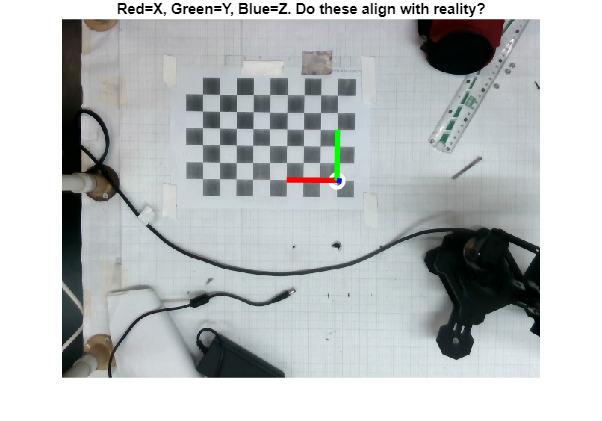


% --- 7. VISUAL SANITY CHECK ---
figure('Name', 'Coordinate Frame Verification');
imshow(img); hold on;

% Draw the XYZ axes projecting from the physical board
axisLength = squareSize * 3; 
worldAxes = [0, 0, 0; axisLength, 0, 0; 0, axisLength, 0; 0, 0, -axisLength]; 
imageAxes = worldToImage(cameraParams, R_cam_board, t_cam_board, worldAxes);

plot(imageAxes(1,1), imageAxes(1,2), 'wo', 'MarkerSize', 10, 'LineWidth', 3);
plot([imageAxes(1,1), imageAxes(2,1)], [imageAxes(1,2), imageAxes(2,2)], 'r-', 'LineWidth', 4); % X Axis
plot([imageAxes(1,1), imageAxes(3,1)], [imageAxes(1,2), imageAxes(3,2)], 'g-', 'LineWidth', 4); % Y Axis
plot([imageAxes(1,1), imageAxes(4,1)], [imageAxes(1,2), imageAxes(4,2)], 'b-', 'LineWidth', 4); % Z Axis

title('Red=X, Green=Y, Blue=Z. Do these align with reality?');
hold off;

% =========================================================================
% REALSENSE HARDWARE CALIBRATION SCRIPT (Intrinsics + Extrinsics)
% =========================================================================

% --- 1. CONFIGURATION ---
% EXACT measured size of one checkerboard square in meters
squareSize = 0.025; 

% --- 2. INITIALIZE REALSENSE PIPELINE ---
pipe = realsense.pipeline();
cfg = realsense.config();

% Enable Color Stream (Depth is not strictly needed for the checkerboard math, 
% but we keep it aligned as per your setup)
cfg.enable_stream(realsense.stream.depth, 640, 480, realsense.format.z16, 30);
cfg.enable_stream(realsense.stream.color, 640, 480, realsense.format.rgb8, 30);

align_to_color = realsense.align(realsense.stream.color);

disp('Starting pipeline and warming up camera...');

Starting pipeline and warming up camera...


profile = pipe.start(cfg);

% --- 3. EXTRACT HARDWARE INTRINSICS DIRECTLY FROM CAMERA ---
% Get the color stream profile and extract the factory-calibrated intrinsics
color_stream = profile.get_stream(realsense.stream.color).as('video_stream_profile');
rs_intrinsics = color_stream.get_intrinsics();

% Convert RealSense intrinsics into a MATLAB cameraIntrinsics object
focalLength    = double([rs_intrinsics.fx, rs_intrinsics.fy]);
principalPoint = double([rs_intrinsics.ppx, rs_intrinsics.ppy]);
imageSize      = double([rs_intrinsics.height, rs_intrinsics.width]);

% Create the MATLAB object needed for the extrinsics math
cameraParams = cameraIntrinsics(focalLength, principalPoint, imageSize);
disp('Factory Intrinsics Loaded Successfully.');

Factory Intrinsics Loaded Successfully.



% --- 4. WARMUP & CAPTURE ---
% Allow auto-exposure to settle before capturing the calibration frame
for i = 1:30
    fs = pipe.wait_for_frames();
end

% Capture the final frame for calibration
fs = align_to_color.process(fs);
color_frame = fs.get_color_frame();

% Extract RGB Image
color_data = color_frame.get_data();
img = permute(reshape(color_data', [3, 640, 480]), [3 2 1]);

% Stop streaming immediately to free up USB bandwidth
pipe.stop();
disp('Image Captured. Pipeline stopped.');

Image Captured. Pipeline stopped.



% --- 5. DETECT CHECKERBOARD & CALCULATE WORLD FRAME ---
disp('Detecting checkerboard origin...');

Detecting checkerboard origin...


[imagePoints, boardSizeDetected] = detectCheckerboardPoints(img);

if isempty(imagePoints)
    error('CRITICAL FAILURE: Could not detect checkerboard. Check lighting.');
end

CRITICAL FAILURE: Could not detect checkerboard. Check lighting.


% Generate Ideal World Points (Setting the Origin to Top-Left Interior Corner)
worldPoints = generateCheckerboardPoints(boardSizeDetected, squareSize)

% Estimate Extrinsics (Board relative to Camera)
camExtrinsics = estimateExtrinsics(imagePoints, worldPoints, cameraParams);

% Build the 4x4 Transformation Matrix (Camera views the World)
R_cam_board=camExtrinsics.R';
t_cam_board=camExtrinsics.Translation;
T_camera_world = eye(4);
T_camera_world(1:3, 1:3) = R_cam_board;
T_camera_world(1:3, 4) = t_cam_board'; 

% Invert the Matrix (World views the Camera) -> ^(world)T_(camera)
% T_world_camera = inv(T_camera_world);
% Extract Rotation and Translation
R = T_camera_world(1:3, 1:3);
p = T_camera_world(1:3, 4);

% Analytical Inverse: [R^T, -R^T*p; 0, 1]
T_world_camera_old = eye(4);
T_world_camera_old(1:3, 1:3) = R';
T_world_camera_old(1:3, 4)   = -R' * p;

% PRE-MULTIPLY to align the World Frame (Swap X/Y, Flip Z)
T_align = [0 1 0 0; 1 0 0 0; 0 0 -1 0; 0 0 0 1];
T_world_camera = T_align * T_world_camera_old;

% IMPORTANT: Update R_cam_board and t_cam_board so Section 7 draws correctly!
% Since T_world_camera = inv(T_camera_world), we must re-invert to get the projection vars
T_camera_world_new = inv(T_world_camera); % Using inv() here is fine for the visualizer
R_cam_board = T_camera_world_new(1:3, 1:3);
t_cam_board = T_camera_world_new(1:3, 4)';

% --- 6. TERMINAL OUTPUT ---
fprintf('\n======================================================\n');
fprintf('FINAL CAMERA-TO-WORLD TRANSFORMATION MATRIX\n');
fprintf('==============================s========================\n');
disp(T_world_camera);
fprintf('Camera Position relative to Checkerboard Origin:\n');
fprintf('X: %8.4f meters\n', T_world_camera(1, 4));
fprintf('Y: %8.4f meters\n', T_world_camera(2, 4));
fprintf('Z: %8.4f meters\n', T_world_camera(3, 4));
fprintf('======================================================\n\n');

% --- 7. VISUAL SANITY CHECK ---
figure('Name', 'Coordinate Frame Verification');
imshow(img); hold on;

% Draw the XYZ axes projecting from the physical board
axisLength = squareSize * 3; 
worldAxes = [0, 0, 0; axisLength, 0, 0; 0, axisLength, 0; 0, 0, -axisLength]; 
imageAxes = worldToImage(cameraParams, R_cam_board, t_cam_board, worldAxes);

plot(imageAxes(1,1), imageAxes(1,2), 'wo', 'MarkerSize', 10, 'LineWidth', 3);
plot([imageAxes(1,1), imageAxes(2,1)], [imageAxes(1,2), imageAxes(2,2)], 'r-', 'LineWidth', 4); % X Axis
plot([imageAxes(1,1), imageAxes(3,1)], [imageAxes(1,2), imageAxes(3,2)], 'g-', 'LineWidth', 4); % Y Axis
plot([imageAxes(1,1), imageAxes(4,1)], [imageAxes(1,2), imageAxes(4,2)], 'b-', 'LineWidth', 4); % Z Axis

title('Red=X, Green=Y, Blue=Z. Do these align with reality?');
hold off;

clear; clc;

%% =================================================================
%% 1. CAMERA PERCEPTION (FIND BLUE OBJECT)
%% =================================================================
% Initialize pipeline and config
pipe = realsense.pipeline();
cfg = realsense.config();

% Enable streams (Note: Changed bgr8 to rgb8 for easier MATLAB color processing)
cfg.enable_stream(realsense.stream.depth, 640, 480, realsense.format.z16, 30);
cfg.enable_stream(realsense.stream.color, 640, 480, realsense.format.rgb8, 30);

% Initialize pointcloud object
pc = realsense.pointcloud();

% Create align object to ensure depth perfectly matches color pixels
align_to_color = realsense.align(realsense.stream.color);

% Start pipeline
profile = pipe.start(cfg);

disp('Warming up camera...');

Warming up camera...


i = 0;
while i < 5
    % Wait for frames
    fs = pipe.wait_for_frames();
    
    % Align frames so depth and color pixels correspond 1:1
    fs = align_to_color.process(fs);
    
    % Get depth frame
    depth_frame = fs.get_depth_frame();
    
    % Get color frame
    color_frame = fs.get_color_frame();
    
    i = i + 1;
    
    % Map pointcloud to color and calculate points
    pc.map_to(color_frame);
    points = pc.calculate(depth_frame);
    
    % Get vertices natively
    vtx = points.get_vertices();
    
    fprintf('Processed frame %d/5\n', i);
end

Processed frame 1/5
Processed frame 2/5
Processed frame 3/5
Processed frame 4/5
Processed frame 5/5



% Stop streaming
pipe.stop();
disp('Camera stopped. Processing final frame for Blue Objects...');

Camera stopped. Processing final frame for Blue Objects...



% --- Extract RGB Image ---
color_data = color_frame.get_data();
I = permute(reshape(color_data', [3, 640, 480]), [3 2 1]);

% --- 2D HSV Color Segmentation (BLUE) ---
hsvI = rgb2hsv(I);
H = hsvI(:,:,1); 
S = hsvI(:,:,2); 
V = hsvI(:,:,3);

% STRICTER COLOR THRESHOLDS
hueMask = (H > 0.52) & (H < 0.65); 
level = max(graythresh(S), 0.40); 
mask = hueMask & (S > level) & (V > 0.25); 

% Clean up the mask (remove noise, fill holes)
mask = bwareaopen(mask, 100); 
mask = imfill(mask, 'holes');

% GEOMETRIC FILTERING
stats = regionprops(mask, 'Area', 'PixelIdxList', 'Solidity');
robust_mask = false(size(mask));

for j = 1:length(stats)
    if stats(j).Area > 300 && stats(j).Area < 15000 && stats(j).Solidity > 0.80
        robust_mask(stats(j).PixelIdxList) = true;
    end
end
mask = robust_mask;

% --- Filter the Point Cloud ---
mask_1d = reshape(mask', [], 1);
valid_depth = (vtx(:,3) > 0); 
blue_indices = valid_depth & mask_1d;
blue_vtx = vtx(blue_indices, :);

if isempty(blue_vtx)
    disp('No blue objects found in the 3D space! Aborting sequence.');
    return;
end

disp('Clustering Point Cloud to remove noise...');

Clustering Point Cloud to remove noise...


ptCloud = pointCloud(blue_vtx);
[labels, numClusters] = pcsegdist(ptCloud, 0.008);

if numClusters == 0
    disp('Could not find a distinct physical object. Aborting sequence.');
    return;
end

% Find the largest dense cluster
clusterSizes = zeros(numClusters, 1);
for c = 1:numClusters
    clusterSizes(c) = sum(labels == c);
end
[~, biggestClusterIdx] = max(clusterSizes);

cubeIndices = find(labels == biggestClusterIdx);
cubeCloud = select(ptCloud, cubeIndices);

% Calculate the centroid of ONLY the clustered cube
pos_cam = mean(cubeCloud.Location, 1);

T_world_camera =  [-0.0105   -0.9991   -0.0408    0.0065
   -0.9999    0.0103    0.0047    0.0586
   -0.0043    0.0408   -0.9992    0.711
         0         0         0    1.0000]

T_world_camera =    -0.0105   -0.9991   -0.0408    0.0065
   -0.9999    0.0103    0.0047    0.0586
   -0.0043    0.0408   -0.9992    0.7110
         0         0         0    1.0000



pos_cam_homog = [pos_cam(1); pos_cam(2); pos_cam(3); 1];
pos_world_homog = T_world_camera * pos_cam_homog;
pos_world = pos_world_homog(1:3)';

fprintf('\n--- TARGET DETECTED (Clustered) ---\n');


--- TARGET DETECTED (Clustered) ---


fprintf('World X: %.3f mm\n', pos_world(1)*1000);

World X: 144.897 mm


fprintf('World Y: %.3f mm\n', pos_world(2)*1000);

World Y: -1.782 mm


fprintf('World Z: %.3f m\n', pos_world(3));

World Z: 0.029 m


fprintf('-----------------------------------\n\n');

-----------------------------------





%% =================================================================
%% 2. DEFINE TARGET COORDINATES FOR ROBOT [X, Y, Z, Phi]
%% =================================================================
disp('Calculating Robot Waypoints...');

Calculating Robot Waypoints...



% Convert world coordinates to millimeters for the robot
% Apply the requested Z-offset: 0.683 + world_Z
pick_x = pos_world(1) * 1000;
pick_y = pos_world(2) * 1000;
pick_z = pos_world(3) * 1000;

% Setup Pick and Place Arrays
pick  = [pick_x, pick_y, pick_z, deg2rad(175)]  

pick =   144.8973   -1.7817   29.3011    3.0543


place = [160,    0,      36,     deg2rad(175)];    

% Calculate pre-pick and pre-place (50mm exactly above targets)
z_offset_mm = 60;
pre_pick  = pick  + [0, 0, z_offset_mm, 0];
pre_place = place + [0, 0, z_offset_mm, 0];

% Gripper & Speed Values
jaw_open_val  = 34;
jaw_close_val = 28;
speed = 100;


%% =================================================================
%% 3. INITIALIZE ROBOT CONNECTION
%% =================================================================
port = 'COM5'; 
numServos = 5; 

try
    arb = Arbotix('port', port, 'nservos', numServos);
    fprintf('Successfully connected to Pincher on %s\n\n', port);
catch
    error('Could not connect. Ensure %s is free and the robot is powered on.', port);
end

serPort COM5is in use.   Closing it.


i = 4

Successfully connected to Pincher on COM5




% --- NEW CODE: SET COMPLIANCE MARGIN TO 0 ---
disp('Maximizing servo stiffness (Setting Compliance Margin to 0)...');

Maximizing servo stiffness (Setting Compliance Margin to 0)...



ADDR_CW_COMPLIANCE_MARGIN = 26;
ADDR_CCW_COMPLIANCE_MARGIN = 27;
margin_val = 2;

% Loop through all your servos (joints 1-4 and gripper 5)

arb.writedata1(1, ADDR_CW_COMPLIANCE_MARGIN, 2);
arb.writedata1(1, ADDR_CCW_COMPLIANCE_MARGIN, 2);


arb.writedata1(2, ADDR_CW_COMPLIANCE_MARGIN, 8);
arb.writedata1(2, ADDR_CCW_COMPLIANCE_MARGIN, 8);


pause(0.5); % Give the motors a moment to register the change
disp('Stiffness maximized.');

Stiffness maximized.


%% =================================================================
%% 4. EXECUTE PICK AND PLACE SEQUENCE
%% =================================================================

% A. Open Gripper & Go Home
fprintf('Opening Jaw and Homing Robot...\n');

Opening Jaw and Homing Robot...


[~, th_open] = positionJaw(jaw_open_val);
arb.setpos(5, th_open, speed);

for i = 1:4
    arb.setpos(i, 0, speed);
end
pause(3);

% B. Move to Pre-Pick, then Pick
fprintf('Moving to Pre-Pick [%.1f, %.1f, %.1f]...\n', pre_pick(1), pre_pick(2), pre_pick(3));

Moving to Pre-Pick [144.9, -1.8, 89.3]...


moveRobotToTarget(arb, pre_pick, speed, 5); 

theta1_sols =    -0.0660    3.0756



fprintf('Moving down to Pick [%.1f, %.1f, %.1f]...\n', pick(1), pick(2), pick(3));

Moving down to Pick [144.9, -1.8, 29.3]...


moveRobotToTarget(arb, pick, speed, 3);     

theta1_sols =    -0.0660    3.0756



% C. Close Gripper (Grab)
fprintf('Closing Jaw to grab object...\n');

Closing Jaw to grab object...


[~, th_close] = positionJaw(jaw_close_val);
arb.setpos(5, th_close, speed);
pause(2);

% D. Read Gripper Load
% gripper_id = 5; 
% addr = 40;      % Starting address for Present Load
% len = 2;        % Read 2 bytes
% response = arb.readdata(gripper_id, addr, len);
% low_byte = response.params(1);
% high_byte = response.params(2);
% raw_load = low_byte + (high_byte * 256);
% fprintf('--> The raw present load on gripper is: %d\n', raw_load);

% E. Move to Pre-Pick (to avoid dragging the object), then Home
fprintf('Moving up to Pre-Pick...\n');

Moving up to Pre-Pick...


moveRobotToTarget(arb, pre_pick, speed, 2);

theta1_sols =    -0.0660    3.0756



fprintf('Returning to Home position...\n');

Returning to Home position...


for i = 1:4
    arb.setpos(i, 0, speed);
end
pause(4);

% F. Move to Pre-Place, then Place
fprintf('Moving across to Pre-Place...\n');

Moving across to Pre-Place...


moveRobotToTarget(arb, pre_place, speed, 4);

theta1_sols =    -0.0524    3.0892



fprintf('Moving down to Place...\n');

Moving down to Place...


moveRobotToTarget(arb, place, speed, 2);

theta1_sols =    -0.0524    3.0892



% G. Open Gripper
fprintf('Opening Jaw to release object...\n');

Opening Jaw to release object...


arb.setpos(5, th_open, speed);
pause(2);

% H. Move back up to Pre-Place, then Home
fprintf('Moving up to Pre-Place...\n');

Moving up to Pre-Place...


moveRobotToTarget(arb, pre_place, speed, 2);

theta1_sols =    -0.0524    3.0892



fprintf('Returning to Home position...\n');

Returning to Home position...


for i = 1:4
    arb.setpos(i, 0, speed);
end
pause(4); 

fprintf('Sequence Complete!\n');

Sequence Complete!


function moveRobotToTarget(arb, target, speed, pause_time)

    fullConfig = zeros(1, 4);
    for i = 1:4
        pos = arb.getpos(i);
        if ~isempty(pos)
            fullConfig(i) = pos;
        end
    end
    
    % --- THE COMBINED FRAME CALIBRATION ---
    dx = 10.258;  
    dy = -3.814;  
    
    x_shifted = target(1) + dx;
    y_shifted = target(2) + dy;
    
    angle_offset_deg = -1.717; 
    theta = deg2rad(angle_offset_deg);
    
    x_corrected = x_shifted * cos(theta) - y_shifted * sin(theta);
    y_corrected = x_shifted * sin(theta) + y_shifted * cos(theta);
    
    % ==========================================
    % NEW: PURE MATH DYNAMIC PHI 
    % ==========================================
    % 1. Find the base angle in radians
    theta1_ideal_deg = rad2deg(atan2(y_corrected, x_corrected));
    
    % 2. Map Phi to specific physical zones
    if theta1_ideal_deg > -45 && theta1_ideal_deg <= 135
        % ZONE 1: Front and Left (+X and +Y regions)
        % You confirmed 175 works great here.
        dynamic_phi_deg = 175;
        
    elseif theta1_ideal_deg > -135 && theta1_ideal_deg <= -45
        % ZONE 2: Right side (-Y region)
        % This is the tricky 4th quadrant where it binds. Force straight down.
        dynamic_phi_deg = 178;
        
    else
        % ZONE 3: Backwards (-X region)
        % Reaching over its shoulder (> 135 or < -135 degrees). Flip outward.
        dynamic_phi_deg = 185;
    end
    
    % 3. Extreme Reach Override (Keep this as a safety net)
    radius = sqrt(x_corrected^2 + y_corrected^2);
    if radius > 185
        dynamic_phi_deg = 180; 
    end
    
    dynamic_phi = deg2rad(dynamic_phi_deg);
    % ==========================================

    % Feed the fully corrected X, Y, and the newly calculated dynamic_phi
    solutions = findSolution(x_corrected, y_corrected, target(3), dynamic_phi, fullConfig);
    
    if isempty(solutions)
        error('IK Solver failed: No valid joint angles found for this target.');
    end
    
    for joint = 1:4
        arb.setpos(joint, solutions(joint), speed);
    end
    pause(pause_time);
end

## Testing calibration

clear; clc; close all;

%% =================================================================
%% 1. INITIALIZATION (ROBOT & CAMERA)
%% =================================================================
num_calibration_points = 25; % Number of points to collect (5 is recommended)

% --- Initialize Robot ---
port = 'COM5'; 
numServos = 5; 
try
    arb = Arbotix('port', port, 'nservos', numServos);
    fprintf('Successfully connected to Pincher on %s\n', port);
catch
    error('Could not connect. Ensure %s is free and the robot is powered on.', port);
end

serPort COM5is in use.   Closing it.


i = 4

Successfully connected to Pincher on COM5




% --- Initialize Camera ---
disp('Starting RealSense Camera Pipeline...');

Starting RealSense Camera Pipeline...


pipe = realsense.pipeline();
cfg = realsense.config();
cfg.enable_stream(realsense.stream.depth, 640, 480, realsense.format.z16, 30);
cfg.enable_stream(realsense.stream.color, 640, 480, realsense.format.rgb8, 30);
align_to_color = realsense.align(realsense.stream.color);
profile = pipe.start(cfg);

pc = realsense.pointcloud();

% Arrays to hold our paired data
camera_points = zeros(num_calibration_points, 2); % [X, Y]
robot_points  = zeros(num_calibration_points, 2); % [X, Y]

%% =================================================================
%% 2. DATA COLLECTION LOOP
%% =================================================================
fprintf('\n--- STARTING CALIBRATION ROUTINE ---\n');


--- STARTING CALIBRATION ROUTINE ---



% Transformation matrix from your checkerboard
T_world_camera =  [-0.0105   -0.9991   -0.0408    0.0065;
                   -0.9999    0.0103    0.0047    0.0586;
                   -0.0043    0.0408   -0.9992    0.7110;
                         0         0         0    1.0000];

for p = 1:num_calibration_points
    fprintf('\n--- POINT %d OF %d ---\n', p, num_calibration_points);
    
    % ---------------------------------------------------------
    % STEP A: CAPTURE CAMERA TARGET
    % ---------------------------------------------------------
    disp('1. Place the blue cube on the table.');
    disp('2. Move the robot arm out of the camera''s view.');
    input('   Press ENTER to scan the cube with the camera...', 's');
    
    % Flush old frames and grab a fresh one
    for warmup = 1:10
        fs = pipe.wait_for_frames();
    end
    fs = align_to_color.process(fs);
    depth_frame = fs.get_depth_frame();
    color_frame = fs.get_color_frame();
    
    pc.map_to(color_frame);
    points = pc.calculate(depth_frame);
    vtx = points.get_vertices();
    
    color_data = color_frame.get_data();
    I = permute(reshape(color_data', [3, 640, 480]), [3 2 1]);
    
    % Color Segmentation (Blue)
    hsvI = rgb2hsv(I);
    H = hsvI(:,:,1); S = hsvI(:,:,2); V = hsvI(:,:,3);
    hueMask = (H > 0.52) & (H < 0.65); 
    level = max(graythresh(S), 0.40); 
    mask = hueMask & (S > level) & (V > 0.25); 
    mask = imfill(bwareaopen(mask, 100), 'holes');
    
    % Point cloud filtering
    mask_1d = reshape(mask', [], 1);
    blue_vtx = vtx((vtx(:,3) > 0) & mask_1d, :);
    
    if isempty(blue_vtx)
        error('Could not see the blue cube! Restart script.');
    end
    
    ptCloud = pointCloud(blue_vtx);
    [labels, numClusters] = pcsegdist(ptCloud, 0.008);
    clusterSizes = arrayfun(@(x) sum(labels==x), 1:numClusters);
    [~, biggest] = max(clusterSizes);
    cubeCloud = select(ptCloud, find(labels == biggest));
    
    % Calculate Camera XYZ in mm
    pos_cam = mean(cubeCloud.Location, 1);
    pos_world_homog = T_world_camera * [pos_cam(1); pos_cam(2); pos_cam(3); 1];
    cam_x = pos_world_homog(1) * 1000;
    cam_y = pos_world_homog(2) * 1000;
    
    fprintf('   Camera sees cube at: X = %.1f, Y = %.1f\n', cam_x, cam_y);
    camera_points(p, :) = [cam_x, cam_y];
    
    % ---------------------------------------------------------
    % STEP B: CAPTURE PHYSICAL ROBOT POSITION
    % ---------------------------------------------------------
    % Relax motors (Turn off Torque)
    for id = 1:4
        arb.relax(id); % Assumes your class has a relax function
    end
    
    disp('3. The robot motors are now relaxed.');
    disp('4. Physically jog the gripper so it is perfectly grasping the cube.');
    input('   Press ENTER to record the physical joint positions...', 's');
    
    % Read joints with a safety retry loop
    q_current = zeros(1,4);
    for id = 1:4
        pos = []; % Reset pos to empty
        
        % Keep asking the motor for its position until it replies
        while isempty(pos)
            pos = arb.getpos(id);
            if isempty(pos)
                pause(0.05); % Wait 50 milliseconds before asking again
            end
        end
        
        % Once we safely have a number, store it
        q_current(id) = pos;
    end
    
    % Calculate Forward Kinematics to get actual XYZ
    [rob_x, rob_y, rob_z, R1, th1, ph1] = pincherFK(q_current);
    
    fprintf('   Robot is actually at: X = %.1f, Y = %.1f\n', rob_x, rob_y);
    robot_points(p, :) = [rob_x, rob_y];
    
end


--- POINT 1 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 151.3, Y = -2.3


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 158.3, Y = -6.5



--- POINT 2 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 99.0, Y = -2.5


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 98.1, Y = -6.0



--- POINT 3 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 116.6, Y = 54.9


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 123.6, Y = 49.1



--- POINT 4 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 83.5, Y = 100.0


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 93.8, Y = 98.2



--- POINT 5 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 37.6, Y = 135.3


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 51.0, Y = 131.9



--- POINT 6 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 3.5, Y = 168.9


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 14.8, Y = 167.8



--- POINT 7 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 2.7, Y = 117.6


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 13.8, Y = 115.6



--- POINT 8 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -43.8, Y = 144.0


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -32.3, Y = 145.3



--- POINT 9 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -90.3, Y = 132.8


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -79.7, Y = 132.7



--- POINT 10 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -111.0, Y = 126.2


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -104.2, Y = 129.1



--- POINT 11 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -153.1, Y = 47.9


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -143.3, Y = 46.2



--- POINT 12 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -162.5, Y = 3.0


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -153.1, Y = 0.8



--- POINT 13 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -164.4, Y = -19.9


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -147.7, Y = -19.7



--- POINT 14 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -152.8, Y = 33.6


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -136.7, Y = 32.8



--- POINT 15 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -178.8, Y = 3.0


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -169.1, Y = 1.7



--- POINT 16 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -160.9, Y = -63.1


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -157.0, Y = -61.5



--- POINT 17 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -145.2, Y = -112.0


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -134.6, Y = -107.7



--- POINT 18 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -94.5, Y = -137.5


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -88.8, Y = -132.9



--- POINT 19 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -43.3, Y = -158.2


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -39.8, Y = -154.9



--- POINT 20 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -9.4, Y = -152.6


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -8.6, Y = -150.8



--- POINT 21 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 31.9, Y = -144.4


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 36.5, Y = -145.2



--- POINT 22 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 75.3, Y = -120.8


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 79.6, Y = -120.4



--- POINT 23 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 116.2, Y = -66.9


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 116.3, Y = -68.4



--- POINT 24 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -92.7, Y = -139.3


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -85.5, Y = -136.9



--- POINT 25 OF 25 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 78.7, Y = -106.4


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 82.0, Y = -109.0



% Stop Camera
pipe.stop();
disp('Data collection complete. Camera stopped.');

Data collection complete. Camera stopped.




%% =================================================================
%% 3. AUTOMATED OPTIMIZER
%% =================================================================
disp('-----------------------------------');

-----------------------------------


disp('Optimizing dx, dy, and angle...');

Optimizing dx, dy, and angle...



% Initial guess: [dx=0, dy=0, angle=0]
initial_guess = [0, 0, 0]; 

% Setup the optimization solver (fminsearch)
options = optimset('Display', 'off', 'TolX', 1e-6, 'TolFun', 1e-6);

% Run the solver to find the parameters that minimize the error
best_params = fminsearch(@(params) calculateError(params, camera_points, robot_points), initial_guess, options);

% Extract the perfect values
best_dx = best_params(1);
best_dy = best_params(2);
best_angle = best_params(3);

fprintf('\n=== PERFECT OFFSETS FOUND ===\n');


=== PERFECT OFFSETS FOUND ===


fprintf('dx: %.3f mm\n', best_dx);

dx: 7.896 mm


fprintf('dy: %.3f mm\n', best_dy);

dy: -0.885 mm


fprintf('Angle Offset: %.3f degrees\n', best_angle);

Angle Offset: -1.104 degrees


fprintf('=============================\n\n');


disp('Use these values in your main script to permanently fix the quadrant error!');

Use these values in your main script to permanently fix the quadrant error!



% =================================================================
% HELPER FUNCTION 
%% =================================================================
function total_error = calculateError(params, cam_pts, rob_pts)
    dx = params(1);
    dy = params(2);
    theta = deg2rad(params(3));

    total_error = 0;

    for i = 1:size(cam_pts, 1)
        x_shifted = cam_pts(i, 1) + dx;
        y_shifted = cam_pts(i, 2) + dy;

        x_calc = x_shifted * cos(theta) - y_shifted * sin(theta);
        y_calc = x_shifted * sin(theta) + y_shifted * cos(theta);

        error_x = x_calc - rob_pts(i, 1);
        error_y = y_calc - rob_pts(i, 2);

        total_error = total_error + (error_x^2 + error_y^2);
    end
end

## updated with z offset

clear; clc; close all;

%% =================================================================
%% 1. INITIALIZATION (ROBOT & CAMERA)
%% =================================================================
num_calibration_points = 15; % Number of points to collect (5 is recommended)

% --- Initialize Robot ---
port = 'COM5'; 
numServos = 5; 
try
    arb = Arbotix('port', port, 'nservos', numServos);
    fprintf('Successfully connected to Pincher on %s\n', port);
catch
    error('Could not connect. Ensure %s is free and the robot is powered on.', port);
end

serPort COM5is in use.   Closing it.


i = 4

Successfully connected to Pincher on COM5



% --- Initialize Camera ---
disp('Starting RealSense Camera Pipeline...');

Starting RealSense Camera Pipeline...


pipe = realsense.pipeline();
cfg = realsense.config();
cfg.enable_stream(realsense.stream.depth, 640, 480, realsense.format.z16, 30);
cfg.enable_stream(realsense.stream.color, 640, 480, realsense.format.rgb8, 30);
align_to_color = realsense.align(realsense.stream.color);
profile = pipe.start(cfg);

pc = realsense.pointcloud();

% Arrays to hold our paired 3D data [X, Y, Z]
camera_points = zeros(num_calibration_points, 3); 
robot_points  = zeros(num_calibration_points, 3); 

%% =================================================================
%% 2. DATA COLLECTION LOOP
%% =================================================================
fprintf('\n--- STARTING CALIBRATION ROUTINE ---\n');


--- STARTING CALIBRATION ROUTINE ---



% Transformation matrix from your checkerboard
T_world_camera =  [-0.0105   -0.9991   -0.0408    0.0065;
                   -0.9999    0.0103    0.0047    0.0586;
                   -0.0043    0.0408   -0.9992    0.7110;
                         0         0         0    1.0000];

for p = 1:num_calibration_points
    fprintf('\n--- POINT %d OF %d ---\n', p, num_calibration_points);
    
    % ---------------------------------------------------------
    % STEP A: CAPTURE CAMERA TARGET
    % ---------------------------------------------------------
    cube_found = false;
    
    while ~cube_found
        disp('1. Place the blue cube on the table.');
        disp('2. Move the robot arm out of the camera''s view.');
        input('   Press ENTER to scan the cube with the camera...', 's');
        
        % Flush old frames and grab a fresh one
        for warmup = 1:10
            fs = pipe.wait_for_frames();
        end
        fs = align_to_color.process(fs);
        depth_frame = fs.get_depth_frame();
        color_frame = fs.get_color_frame();
        
        pc.map_to(color_frame);
        points = pc.calculate(depth_frame);
        vtx = points.get_vertices();
        
        color_data = color_frame.get_data();
        I = permute(reshape(color_data', [3, 640, 480]), [3 2 1]);
        
        % Color Segmentation (Blue)
        hsvI = rgb2hsv(I);
        H = hsvI(:,:,1); S = hsvI(:,:,2); V = hsvI(:,:,3);
        hueMask = (H > 0.52) & (H < 0.65); 
        level = max(graythresh(S), 0.40); 
        mask = hueMask & (S > level) & (V > 0.25); 
        mask = imfill(bwareaopen(mask, 100), 'holes');
        
        % Point cloud filtering
        mask_1d = reshape(mask', [], 1);
        blue_vtx = vtx((vtx(:,3) > 0) & mask_1d, :);
        
        % --- NEW RETRY LOGIC ---
        if isempty(blue_vtx)
            disp(' ');
            disp('⚠️ WARNING: Could not see the blue cube!');
            action = input('   Press ENTER to retake this image, or type "q" to quit: ', 's');
            
            if strcmpi(action, 'q')
                error('Calibration aborted by user.'); % Safe exit if you actually want to stop
            else
                disp('   Retaking image...');
                continue; % Jumps back to the start of the while loop to try again
            end
        end
        
        % If we make it here, the cube was found!
        cube_found = true; 
    end   
    ptCloud = pointCloud(blue_vtx);
    [labels, numClusters] = pcsegdist(ptCloud, 0.008);
    clusterSizes = arrayfun(@(x) sum(labels==x), 1:numClusters);
    [~, biggest] = max(clusterSizes);
    cubeCloud = select(ptCloud, find(labels == biggest));
    
    % Calculate Camera XYZ and convert to mm for unit consistency
    pos_cam = mean(cubeCloud.Location, 1);
    pos_world_homog = T_world_camera * [pos_cam(1); pos_cam(2); pos_cam(3); 1];
    cam_x = pos_world_homog(1) * 1000;
    cam_y = pos_world_homog(2) * 1000;
    cam_z = pos_world_homog(3) * 1000;
    
    fprintf('   Camera sees cube at: X = %.1f, Y = %.1f, Z = %.1f\n', cam_x, cam_y, cam_z);
    camera_points(p, :) = [cam_x, cam_y, cam_z];
    
    % ---------------------------------------------------------
    % STEP B: CAPTURE PHYSICAL ROBOT POSITION
    % ---------------------------------------------------------
    % Relax motors (Turn off Torque)
    for id = 1:4
        arb.relax(id); 
    end
    
    disp('3. The robot motors are now relaxed.');
    disp('4. Physically jog the gripper so it is perfectly grasping the cube.');
    input('   Press ENTER to record the physical joint positions...', 's');
    
    % Read joints with a safety retry loop
    q_current = zeros(1,4);
    for id = 1:4
        pos = []; 
        while isempty(pos)
            pos = arb.getpos(id);
            if isempty(pos)
                pause(0.05); 
            end
        end
        q_current(id) = pos;
    end
    
    % Calculate Forward Kinematics to get actual XYZ
    [rob_x, rob_y, rob_z, R1, th1, ph1] = pincherFK(q_current);
    
    fprintf('   Robot is actually at: X = %.1f, Y = %.1f, Z = %.1f\n', rob_x, rob_y, rob_z);
    robot_points(p, :) = [rob_x, rob_y, rob_z];
    
end


--- POINT 1 OF 15 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 149.6, Y = -0.8, Z = 33.6


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 143.3, Y = -6.6, Z = 11.0



--- POINT 2 OF 15 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 103.0, Y = 94.5, Z = 35.9


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 104.8, Y = 93.1, Z = 13.3



--- POINT 3 OF 15 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 11.4, Y = 144.7, Z = 39.6


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 14.6, Y = 134.6, Z = 13.5



--- POINT 4 OF 15 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -49.4, Y = 129.5, Z = 37.8


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -46.5, Y = 130.8, Z = 14.8



--- POINT 5 OF 15 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -147.1, Y = 1.8, Z = 41.2


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 121.5, Y = 75.7, Z = 17.0



--- POINT 6 OF 15 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -97.8, Y = -135.3, Z = 37.8


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -95.6, Y = -128.9, Z = 16.6



--- POINT 7 OF 15 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -2.0, Y = -150.9, Z = 39.4


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -9.4, Y = -143.1, Z = 14.1



--- POINT 8 OF 15 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 93.4, Y = -106.5, Z = 35.2


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 80.3, Y = -105.5, Z = 13.8



--- POINT 9 OF 15 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 144.7, Y = -1.9, Z = 58.0


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 140.4, Y = -8.6, Z = 26.3



--- POINT 10 OF 15 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 100.9, Y = 122.7, Z = 68.3


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 100.4, Y = 110.5, Z = 43.6



--- POINT 11 OF 15 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 13.2, Y = 141.1, Z = 37.5


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 19.4, Y = 138.5, Z = 14.7



--- POINT 12 OF 15 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -0.3, Y = -136.7, Z = 39.8


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -8.8, Y = -134.0, Z = 13.8



--- POINT 13 OF 15 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 131.5, Y = -0.5, Z = 96.8


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 128.5, Y = -6.6, Z = 78.2



--- POINT 14 OF 15 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = -145.6, Y = -0.2, Z = 64.1


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = -142.6, Y = -2.2, Z = 30.5



--- POINT 15 OF 15 ---


1. Place the blue cube on the table.


2. Move the robot arm out of the camera's view.


   Camera sees cube at: X = 78.0, Y = -122.9, Z = 39.1


3. The robot motors are now relaxed.


4. Physically jog the gripper so it is perfectly grasping the cube.


   Robot is actually at: X = 70.3, Y = -128.0, Z = 13.3



% Stop Camera
pipe.stop();
disp('Data collection complete. Camera stopped.');

Data collection complete. Camera stopped.




%% =================================================================
%% 3. AUTOMATED OPTIMIZER
%% =================================================================
disp('-----------------------------------');

-----------------------------------


disp('Optimizing dx, dy, dz, and angle...');

Optimizing dx, dy, dz, and angle...



% Initial guess: [dx=0, dy=0, dz=0, angle=0]
initial_guess = [0, 0, 0, 0]; 

% Setup the optimization solver (fminsearch)
options = optimset('Display', 'off', 'TolX', 1e-6, 'TolFun', 1e-6);

% Run the solver to find the parameters that minimize the 3D error
best_params = fminsearch(@(params) calculateError(params, camera_points, robot_points), initial_guess, options);

% Extract the perfect values
best_dx = best_params(1);
best_dy = best_params(2);
best_dz = best_params(3);
best_angle = best_params(4);

fprintf('\n=== PERFECT OFFSETS FOUND ===\n');


=== PERFECT OFFSETS FOUND ===


fprintf('dx: %.3f mm\n', best_dx);

dx: 15.508 mm


fprintf('dy: %.3f mm\n', best_dy);

dy: 6.586 mm


fprintf('dz: %.3f mm\n', best_dz);

dz: -24.643 mm


fprintf('Angle Offset: %.3f degrees\n', best_angle);

Angle Offset: -5.339 degrees


fprintf('=============================\n\n');


disp('Use these values in your main script to permanently fix the translation and quadrant errors!');

Use these values in your main script to permanently fix the translation and quadrant errors!



%% =================================================================
%% HELPER FUNCTION 
%% =================================================================
% function total_error = calculateError(params, cam_pts, rob_pts)
%     dx = params(1);
%     dy = params(2);
%     dz = params(3);
%     theta = deg2rad(params(4));
% 
%     total_error = 0;
% 
%     for i = 1:size(cam_pts, 1)
%         % Apply translation offsets
%         x_shifted = cam_pts(i, 1) + dx;
%         y_shifted = cam_pts(i, 2) + dy;
%         z_shifted = cam_pts(i, 3) + dz;
% 
%         % Apply rotation around the Z-axis (Yaw)
%         x_calc = x_shifted * cos(theta) - y_shifted * sin(theta);
%         y_calc = x_shifted * sin(theta) + y_shifted * cos(theta);
%         z_calc = z_shifted; % Z remains unaffected by a Z-axis rotation
% 
%         % Calculate errors in all 3 axes
%         error_x = x_calc - rob_pts(i, 1);
%         error_y = y_calc - rob_pts(i, 2);
%         error_z = z_calc - rob_pts(i, 3);
% 
%         % Sum of squared errors (3D Euclidean distance squared)
%         total_error = total_error + (error_x^2 + error_y^2 + error_z^2);
%     end
% end